# Scientic Computing for differential Equations

## Von Der Pol Problem

mu = 10;
x0 = [2.0; 0.0];
options = odeset('RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X]=ode45(@VanDerPol,[0 5*mu],x0,options,mu);

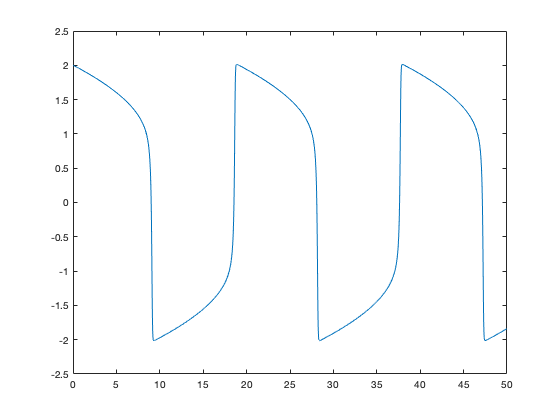

plot(T,X(:,1))

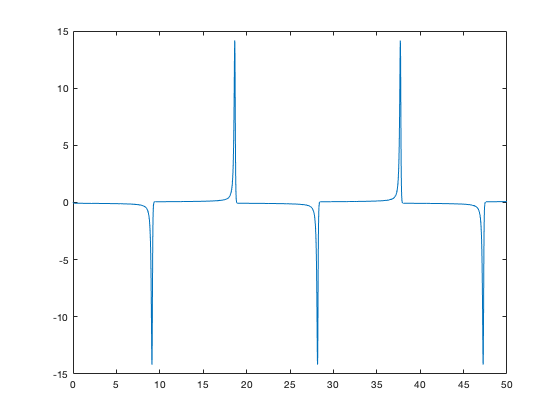

plot(T,X(:,2))

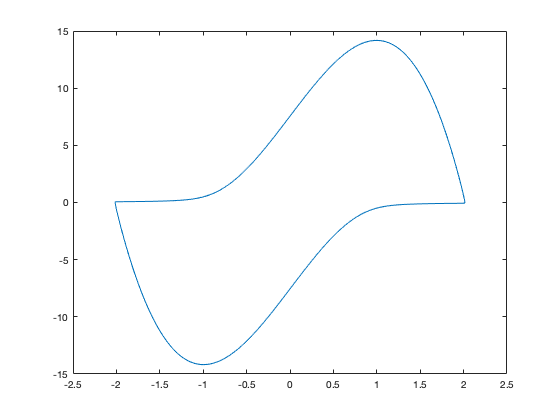

plot(X(:,1),X(:,2))

## Jacobian

mu = 10;
x0 = [2.0; 0.0];
options = odeset('Jacobian',@JacVanDerPol,'RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X]=ode15s(@VanDerPol,[0 5*mu],x0,options,mu);

plot(T,X(:,1))

plot(T,X(:,2))

plot(X(:,1),X(:,2))

## Prey-Predator Problem

a = 1;
b = 1;
x0 = [2; 2];
options = odeset('RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X]=ode45(@PreyPredator,[0 50],x0,options,a,b);

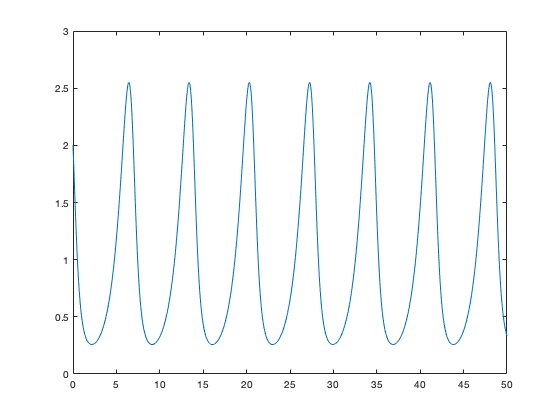

plot(T,X(:,1))

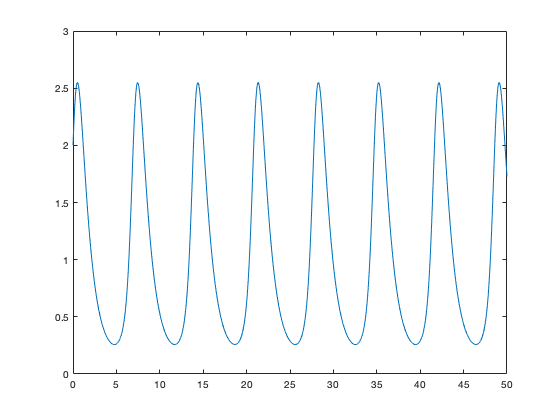

plot(T,X(:,2))

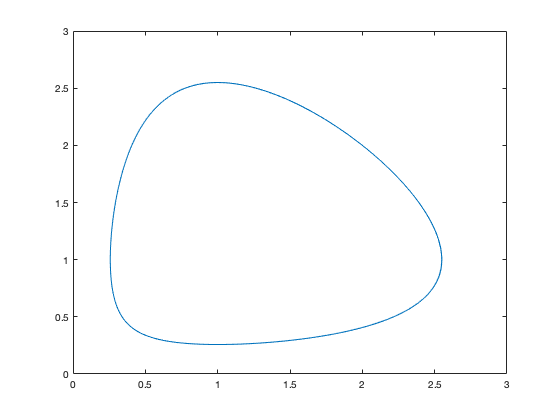

plot(X(:,1),X(:,2))

## The Lorentz Problem - The Lorentz attractor

sigma = 10;
rho = 28;
beta = 8/3;
nu = sqrt(rho*(beta-1));
x0 = [rho-1;nu;nu+3];
options = odeset('RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X]=ode45(@Lorentz,[0 30],x0,options,sigma,rho,beta);

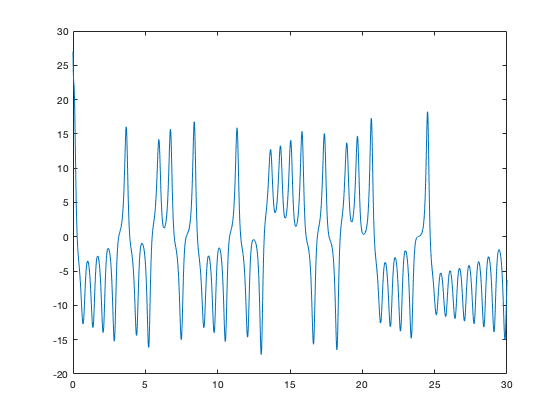

plot(T,X(:,1))

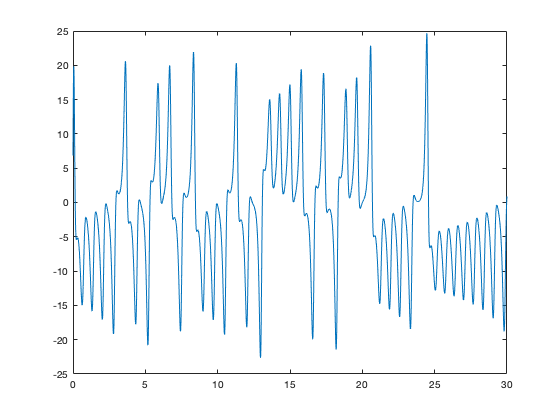

plot(T,X(:,2))

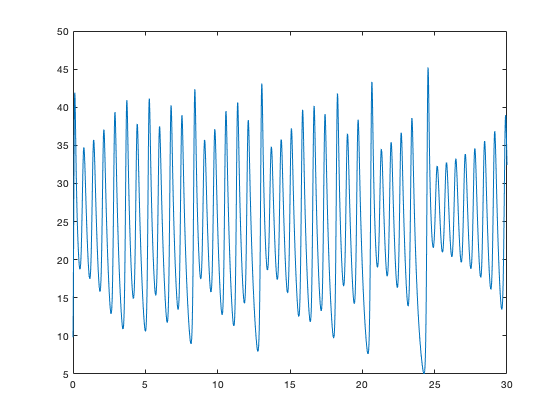

plot(T,X(:,3))

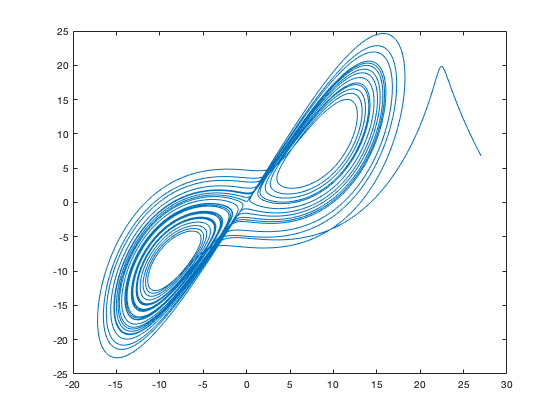

plot(X(:,1),X(:,2))

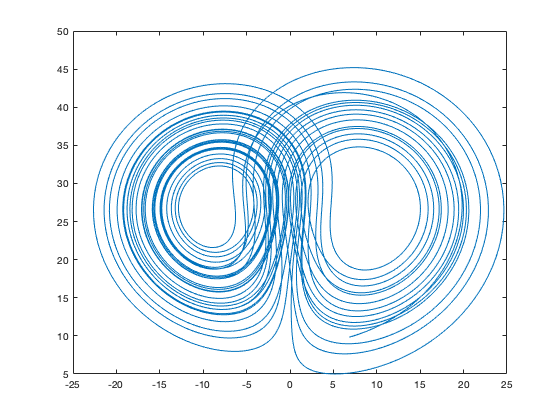

plot(X(:,2),X(:,3))

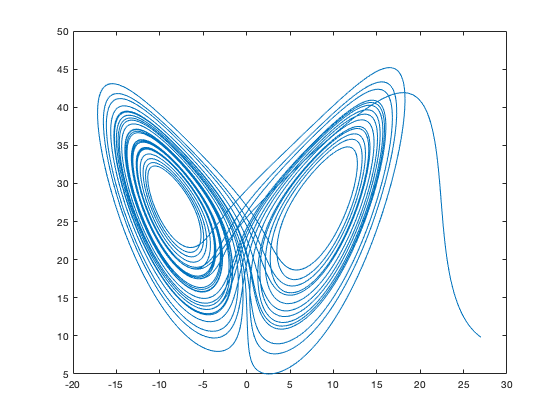

plot(X(:,1),X(:,3))

## The Brusselator Problem

A = 1;
B = 3;
x0 = [4,0];
options = odeset('RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X]=ode45(@Brusselator,[0 100],x0,options,A,B);

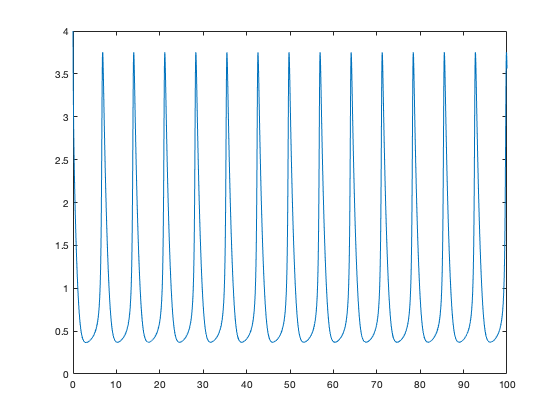

plot(T,X(:,1))

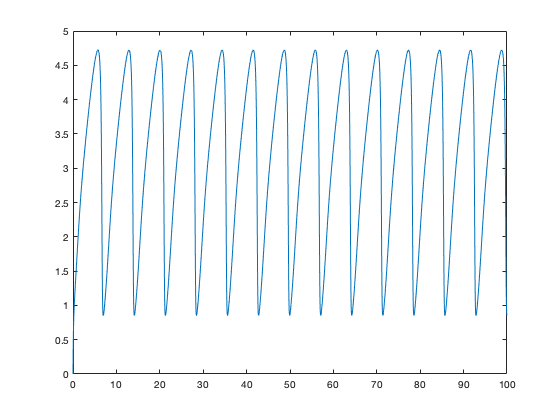

plot(T,X(:,2))

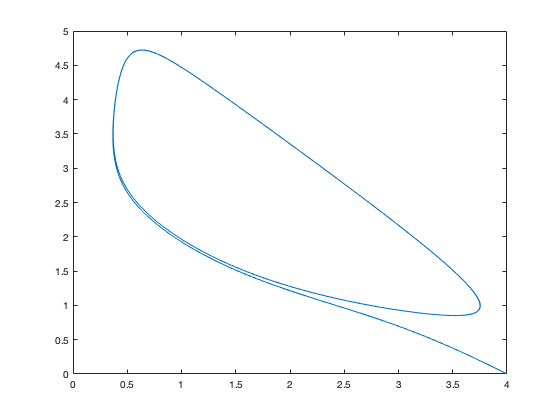

plot(X(:,1),X(:,2))